**1.1**

A = [1 2 3 4; 5 6 7 8; 9 10 11 12]

A =      1     2     3     4
     5     6     7     8
     9    10    11    12


**1.2**

B = randi([3 10], size(A))

B =      9    10     5    10
    10     8     7     4
     4     3    10    10


**1.3**

save("src/FP1/abfile.mat", "A", "B")

**1.4**

clear

**1.5**

load("src/FP1/abfile.mat", "A", "B");

**1.6**

A(2, :) = []

A =      1     2     3     4
     9    10    11    12


B(3, :) = []

B =      9    10     5    10
    10     8     7     4


**1.7**

A = [-3 -2 -1 0; A]

A =     -3    -2    -1     0
     1     2     3     4
     9    10    11    12


B = [B [20; 50]]

B =      9    10     5    10    20
    10     8     7     4    50


1.8

Cp = [A(1:2, 1) B(1:2, end)]

Cp =     -3    20
     1    50


1.9

C = [10 20 30; 40 50 60; 70 80 90]

C =     10    20    30
    40    50    60
    70    80    90


D = [-1 -2 -3; -4 -5 -6; -7 -8 -9]

D =     -1    -2    -3
    -4    -5    -6
    -7    -8    -9


1.9.1

disp("C + D");

C + D


disp(C + D);

     9    18    27
    36    45    54
    63    72    81



1.9.2

disp("C - D");

C - D


disp(C - D);

    11    22    33
    44    55    66
    77    88    99



1.9.3

disp("C * D'");

C * D'


disp(C * D');

        -140        -320        -500
        -320        -770       -1220
        -500       -1220       -1940



1.9.4

disp("C .* D");

C .* D


disp(C .* D);

   -10   -40   -90
  -160  -250  -360
  -490  -640  -810



1.9.5

disp("C / D");

C / D


disp(C / D);

  -10.0000         0   -0.0000
   -5.0000         0   -5.0000
         0         0  -10.0000



1.9.6

disp("C ./ D");

C ./ D


disp(C ./ D);

   -10   -10   -10
   -10   -10   -10
   -10   -10   -10



2.1

t = -15:0.02:15;
disp("Dimensao do vetor tempo: " + length(t));

Dimensao do vetor tempo: 1501


2.2

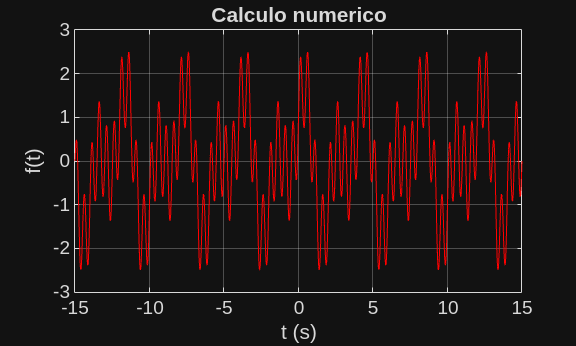

ft = sin(4 * pi * t) + sin(pi * t) + cos(0.5 * pi * t);
figure;
plot(t, ft, 'r');
title("Calculo numerico");
xlabel("t (s)");
ylabel("f(t)");
grid on;

3

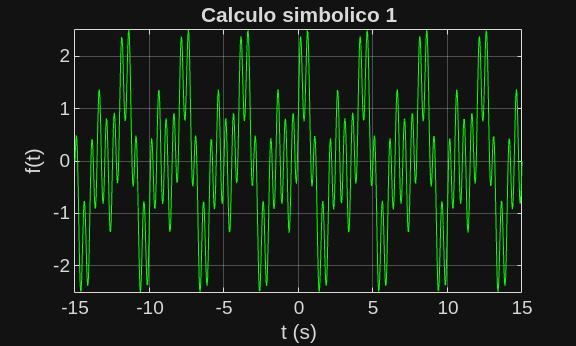

syms tsym
ftsym = sin(4 * pi * tsym) + sin(pi * tsym) + cos(0.5 * pi * tsym);
ft2 = subs(ftsym, tsym, t);

figure;
fplot(tsym, ftsym, [-15 15], 'g');
title("Calculo simbolico 1");
xlabel("t (s)");
ylabel("f(t)");
grid on;

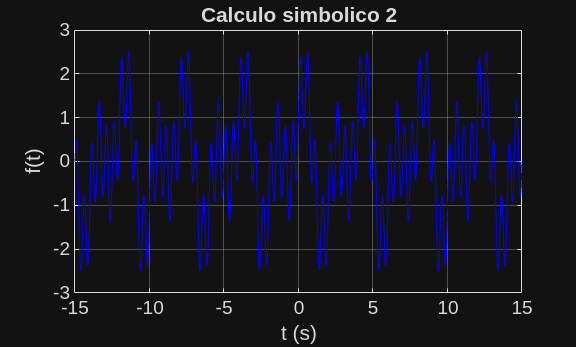


figure;
plot(t, ft2, 'b');
title("Calculo simbolico 2");
xlabel("t (s)");
ylabel("f(t)");
grid on;

4

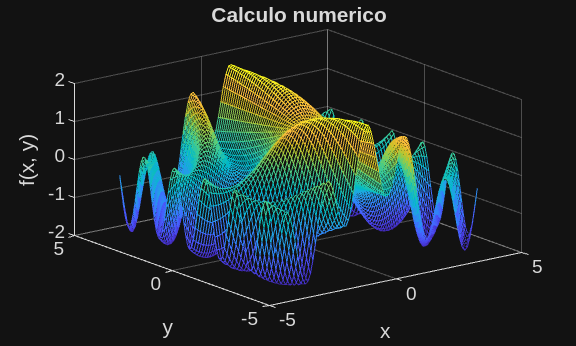

syms x y
xVals = -4:0.1:4;
yVals = xVals;
[X, Y] = meshgrid(xVals, yVals);
fxy = sin(X .* Y) + cos(X);
fxysym = sin(x .* y) + cos(x);

figure;
mesh(X, Y, fxy);
title("Calculo numerico");
xlabel("x");
ylabel("y");
zlabel("f(x, y)");
grid on;

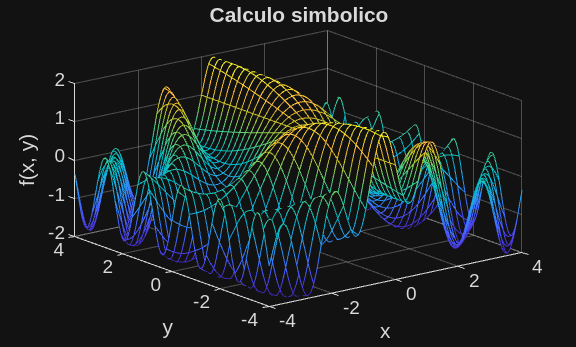


figure;
fmesh(x, y, fxysym, [-4 4 -4 4]);
title("Calculo simbolico");
xlabel("x");
ylabel("y");
zlabel("f(x, y)");
grid on;

5

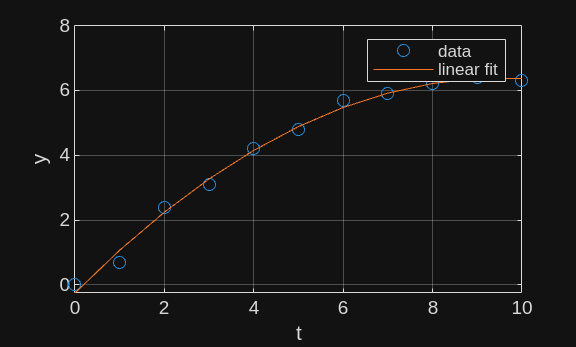

t = 0:10;
y = [0 0.7 2.4 3.1 4.2 4.8 5.7 5.9 6.2 6.4 6.3];
p = polyfit(t, y, 2);
fpoly = polyval(p, t);

figure;
plot(t, y, 'o', t, fpoly, '-');
xlabel("t");
ylabel("y");
legend("data", "linear fit");
grid on;

6

function result = factorial(num)
arguments (Input)
	num
end

arguments (Output)
	result
end

result = 1;
for i = 2:num
	result = result * i;
end
end

disp("O fatorial de 5 e " + factorial(5));

O fatorial de 5 e 120


7

function result = mySqrt(num, err)
arguments (Input)
	num
	err
end

arguments (Output)
	result
end

realResult = sqrt(num);
result = 10;
while abs(result - realResult) >= err
	result = (result + num / result) / 2;
end
end

disp("A raiz quadrada de 2 e " + mySqrt(2, 0.00000000000001));

A raiz quadrada de 2 e 1.4142
